# Kersbergen et al 2022

% Figure 1E, F

% IHC whole cell v clamp recordings, P7
% 2.5K or 6K external, Atp -, gtp - internal, phys temp (32-34C) 
% performed by CJK

% spontaneous activity - 10-15 minute vclamp recordings
% did manual baseline adjustment - too sensitive with automatic. Some weird
% stuff.

[Con1 timeCon1] = loadPclampData('2020_08_09_0010_adjusted.abf');

** abfload
opening 2020_08_09_0010_adjusted.abf..
data were acquired in gap-free mode


[Con2 timeCon2] = loadPclampData('2020_09_03_0018_adjusted.abf');

** abfload
opening 2020_09_03_0018_adjusted.abf..
data were acquired in gap-free mode


[Con3 timeCon3] = loadPclampData('2020_09_03_0021_adjusted.abf');

** abfload
opening 2020_09_03_0021_adjusted.abf..
data were acquired in gap-free mode


[Con4 timeCon4] = loadPclampData('2021_09_30_0003_adjusted.abf'); % 6K

** abfload
opening 2021_09_30_0003_adjusted.abf..
data were acquired in gap-free mode


[Con5 timeCon5] = loadPclampData('2021_09_30_0019_adjusted.abf'); % 6K

** abfload
opening 2021_09_30_0019_adjusted.abf..
data were acquired in gap-free mode


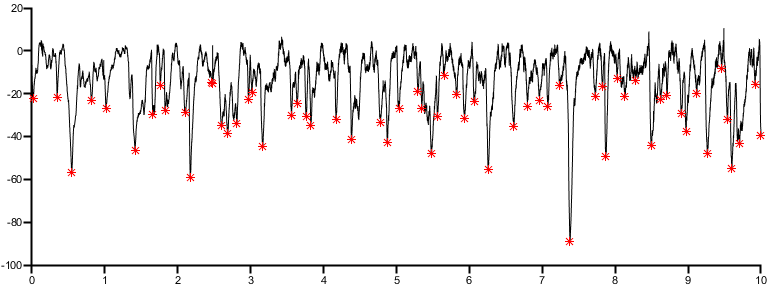

ConFreq1 = 6.2000

ConAmp1 = -30.9141

ConMax1 = 89.0027

ConCharge1 = 12.9956

ConPeaks1 =    22.4608   21.7730   56.6046   23.1519   26.7732   46.4119   29.8475   16.0635   27.9691   28.5883   59.1522   14.8594   15.1261   35.0621   38.4917   33.8994   22.8048   19.4495   44.6439   30.3889   24.5946   30.7434   34.8221   31.8730   41.2893   33.2772   42.9227   27.1496   19.1909   27.1405   48.0304   30.6165   11.6882   20.5714   31.5952   23.7664   55.4069   35.4803   26.0010   23.2383   25.8652   16.0734   89.0027   21.1770   16.7289   49.2178   13.0935   21.4025   13.7469   44.3684



Con1 = msbackadj(timeCon1, -Con1, 'WindowSize', 60,'StepSize',30);
Con2 = msbackadj(timeCon2, -Con2, 'WindowSize', 60,'StepSize',30);
Con3 = msbackadj(timeCon3, -Con3, 'WindowSize', 60,'StepSize',30);
Con4 = msbackadj(timeCon4, -Con4, 'WindowSize', 60,'StepSize',30);
Con5 = msbackadj(timeCon5, -Con5, 'WindowSize', 60,'StepSize',30);

[ConFreq1 ConAmp1 ConMax1 ConCharge1 ConPeaks1] = freqAmpIHC(-Con1(1:3000000), timeCon1(1:3000000)) % 15 min

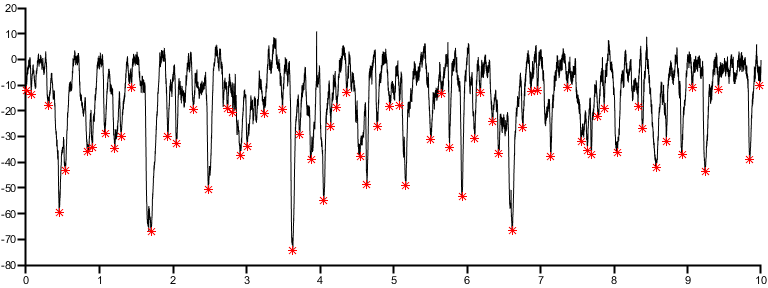

ConFreq2 = 6.5000

ConAmp2 = -30.5069

ConMax2 = 74.2962

ConCharge2 = 13.7976

ConPeaks2 =    12.2241   13.8410   17.8605   59.4236   43.0748   35.7749   34.2202   28.9235   34.6193   29.8997   10.8515   67.0123   30.1304   32.7670   19.6419   50.5312   18.9469   20.5439   37.2875   34.0215   21.0750   19.6070   74.2962   29.2825   38.8709   54.7888   26.2791   18.6747   12.9400   37.8256   48.8122   26.0243   18.3714   17.7679   49.1191   31.3019   13.4223   34.1113   53.3104   30.8337   12.9557   24.0376   36.4248   66.6322   26.4872   12.5440   12.2380   37.9105   11.0675   31.9752


[ConFreq2 ConAmp2 ConMax2 ConCharge2 ConPeaks2] = freqAmpIHC(-Con2(1:3000000), timeCon2(1:3000000)) % 10 min

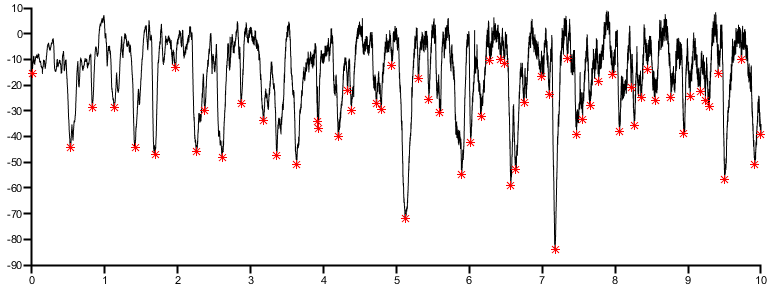

ConFreq3 = 6.1000

ConAmp3 = -31.9699

ConMax3 = 84.1267

ConCharge3 = 14.9581

ConPeaks3 =    15.6453   44.3887   28.6709   28.7415   44.4682   46.8641   13.2083   45.9988   29.9830   48.1865   27.3455   33.7366   47.2471   50.8778   34.2009   37.0522   40.1713   22.1081   29.7688   27.2971   29.5545   12.3805   71.9725   17.5720   25.4772   30.6823   54.9576   42.2823   32.0673   10.4193   10.0854   11.4630   58.8911   52.6924   26.9362   16.7713   23.6827   84.1267    9.6453   39.2986   33.2914   28.0588   18.5196   15.9968   37.9120   21.0269   35.8993   24.9325   14.0192   26.0202


[ConFreq3 ConAmp3 ConMax3 ConCharge3 ConPeaks3] = freqAmpIHC(-Con3(1:3000000), timeCon3(1:3000000)) % 10 min

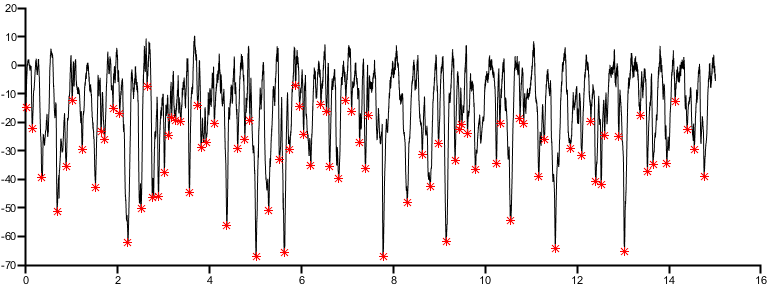

ConFreq4 = 5.5973

ConAmp4 = -31.7661

ConMax4 = 67.1626

ConCharge4 = 14.9172

ConPeaks4 =    14.8324   22.0236   39.4881   51.4185   35.4334   12.2336   29.6157   43.0244   23.1593   25.9830   15.0335   16.8819   62.0132   50.0809    7.6643   46.2143   46.0328   37.6114   24.6805   18.4035   19.4873   19.5848   44.7230   14.0185   28.9825   27.0970   20.6120   56.2167   29.2813   25.8802   19.2563   67.1626   51.0342   33.1753   65.6542   29.5741    7.2103   14.5736   24.3022   35.3076   13.8308   16.1331   35.4542   39.8336   12.2311   16.1141   27.2478   36.1867   17.5975   66.9971


[ConFreq4 ConAmp4 ConMax4 ConCharge4 ConPeaks4] = freqAmpIHC(-Con4, timeCon4) % 15 min

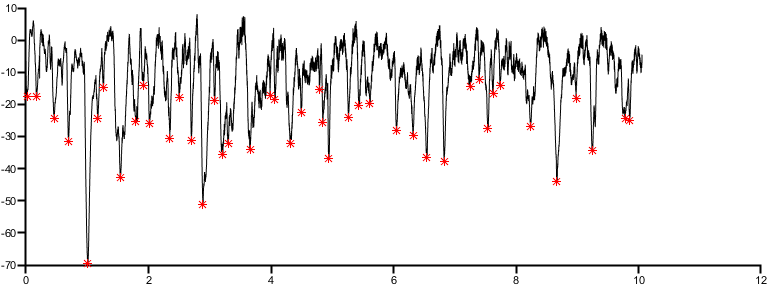

ConFreq5 = 4.3748

ConAmp5 = -26.8590

ConMax5 = 69.5970

ConCharge5 = 11.1817

ConPeaks5 =    17.4411   17.6966   24.3879   31.4233   69.5970   24.5032   14.8694   42.7241   25.3558   14.2594   25.8349   30.5975   17.7085   31.3617   51.0256   18.6407   35.5358   32.0369   34.1366   17.0957   18.5684   32.0863   22.6830   15.3540   25.5074   36.9851   24.1087   20.4625   19.8435   28.2036   29.6588   36.6882   37.7624   14.4919   12.1209   27.4439   16.4764   14.2120   26.7552   44.0040   18.2698   34.3901   24.5412   24.9489


[ConFreq5 ConAmp5 ConMax5 ConCharge5 ConPeaks5] = freqAmpIHC(-Con5, timeCon5) % 10 min


% cKO

[TectaTM1 time1] = loadPclampData('2020_09_03_0009_adjusted.abf');

** abfload
opening 2020_09_03_0009_adjusted.abf..
data were acquired in gap-free mode


[TectaTM2 time2] = loadPclampData('2020_09_03_0034_adjusted.abf');

** abfload
opening 2020_09_03_0034_adjusted.abf..
data were acquired in gap-free mode


[TectaTM3 time3] = loadPclampData('2020_09_03_0037_adjusted.abf');

** abfload
opening 2020_09_03_0037_adjusted.abf..
data were acquired in gap-free mode


[TectaTM4 time4] = loadPclampData('2020_09_03_0003_adjusted.abf');

** abfload
opening 2020_09_03_0003_adjusted.abf..
data were acquired in gap-free mode


[TectaTM5 time5] = loadPclampData('2021_09_30_0017_adjusted.abf'); % 6K

** abfload
opening 2021_09_30_0017_adjusted.abf..
data were acquired in gap-free mode


[TectaTM6 time6] = loadPclampData('2021_09_30_0027_adjusted.abf'); % 6K

** abfload
opening 2021_09_30_0027_adjusted.abf..
data were acquired in gap-free mode


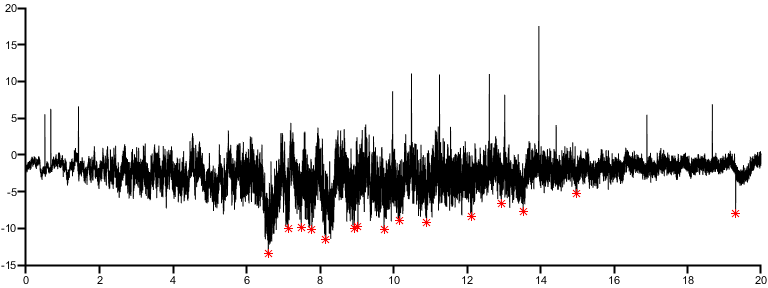

TectaTMFreq1 = 0.7500

TectaTMAmp1 = -9.2706

TectaTMMax1 = 13.4950

TectaTMCharge1 = 2.5799

TectaTMPeaks1 =    13.4950    9.9699    9.8972   10.2284   11.4800   10.0366    9.7331   10.1739    8.9525    9.2377    8.3856    6.5942    7.6629    5.2202    7.9914




TectaTM1 = msbackadj(time1, -TectaTM1, 'WindowSize', 60,'StepSize',30);
TectaTM2 = msbackadj(time2, -TectaTM2, 'WindowSize', 60,'StepSize',30);
TectaTM3 = msbackadj(time3, -TectaTM3, 'WindowSize', 60,'StepSize',30);
TectaTM4 = msbackadj(time4, -TectaTM4, 'WindowSize', 60,'StepSize',30);
TectaTM5 = msbackadj(time5, -TectaTM5, 'WindowSize', 60,'StepSize',30);
TectaTM6 = msbackadj(time6, -TectaTM6, 'WindowSize', 60,'StepSize',30);


[TectaTMFreq1 TectaTMAmp1 TectaTMMax1 TectaTMCharge1 TectaTMPeaks1] = freqAmpIHC(-TectaTM1(1:6000000), time1(1:6000000)) % 15 min

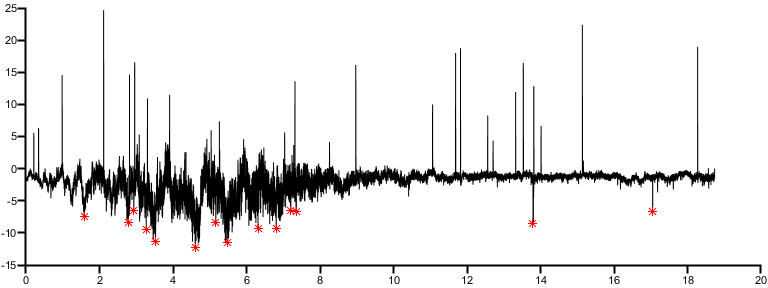

TectaTMFreq2 = 0.7472

TectaTMAmp2 = -8.7404

TectaTMMax2 = 12.2376

TectaTMCharge2 = 2.0722

TectaTMPeaks2 =     7.5072    8.4283    6.5247    9.4327   11.3769   12.2376    8.4312   11.5674    9.2771    9.2658    6.5368    6.6202    8.5337    6.6254


[TectaTMFreq2 TectaTMAmp2 TectaTMMax2 TectaTMCharge2 TectaTMPeaks2] = freqAmpIHC(-TectaTM2, time2) % 15 min

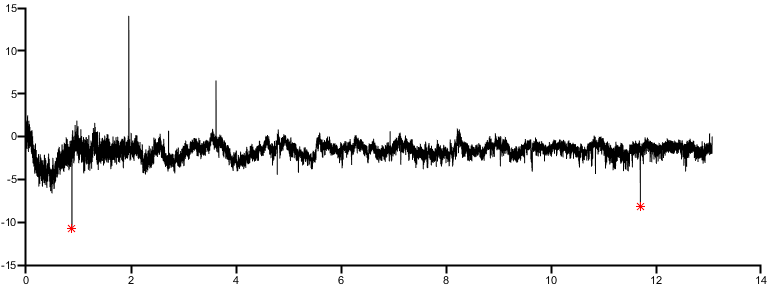

TectaTMFreq3 = 0.1530

TectaTMAmp3 = -9.4676

TectaTMMax3 = 10.7407

TectaTMCharge3 = 1.6603

TectaTMPeaks3 =    10.7407    8.1944


[TectaTMFreq3 TectaTMAmp3 TectaTMMax3 TectaTMCharge3 TectaTMPeaks3] = freqAmpIHC(-TectaTM3, time3) % 15 min

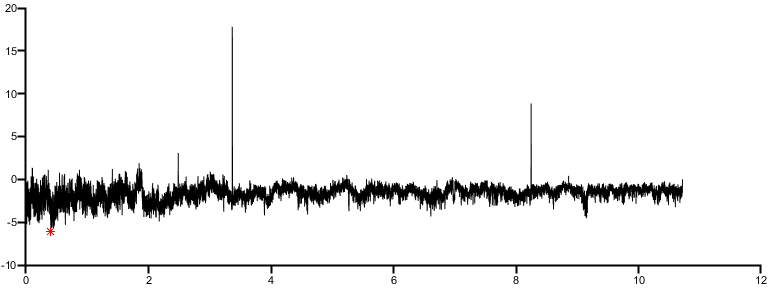

TectaTMFreq4 = 0.0933

TectaTMAmp4 = -6.0396

TectaTMMax4 = 6.0396

TectaTMCharge4 = 1.6071

TectaTMPeaks4 = 6.0396

[TectaTMFreq4 TectaTMAmp4 TectaTMMax4 TectaTMCharge4 TectaTMPeaks4] = freqAmpIHC(-TectaTM4, time4) % 15 min

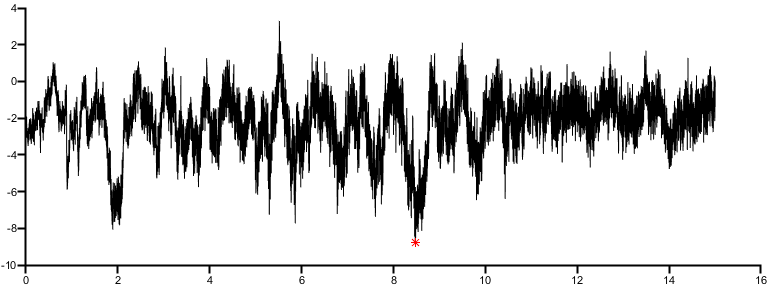

TectaTMFreq5 = 0.0667

TectaTMAmp5 = -8.7780

TectaTMMax5 = 8.7780

TectaTMCharge5 = 2.2035

TectaTMPeaks5 = 8.7780

[TectaTMFreq5 TectaTMAmp5 TectaTMMax5 TectaTMCharge5 TectaTMPeaks5] = freqAmpIHC(-TectaTM5, time5)

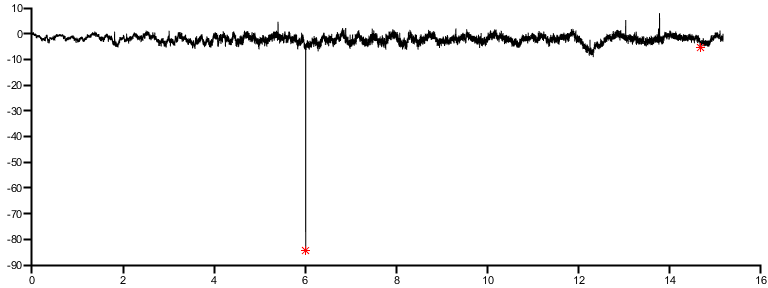

TectaTMFreq6 = 0.1319

TectaTMAmp6 = -44.8234

TectaTMMax6 = 84.4099

TectaTMCharge6 = 2.1377

TectaTMPeaks6 =    84.4099    5.2369


[TectaTMFreq6 TectaTMAmp6 TectaTMMax6 TectaTMCharge6 TectaTMPeaks6] = freqAmpIHC(-TectaTM6, time6)


ConFreq = [ConFreq1,ConFreq2,ConFreq3,ConFreq4,ConFreq5];
ConAmp = abs([ConAmp1,ConAmp2,ConAmp3,ConAmp4,ConAmp5]);
ConMax = [ConMax1,ConMax2,ConMax3,ConMax4,ConMax5];
ConCharge = [ConCharge1,ConCharge2,ConCharge3,ConCharge4,ConCharge5];

TectaTMFreq = [TectaTMFreq1,TectaTMFreq2,TectaTMFreq3,TectaTMFreq4,TectaTMFreq5,TectaTMFreq6];
TectaTMAmp = abs([TectaTMAmp1,TectaTMAmp2,TectaTMAmp3,TectaTMAmp4,TectaTMAmp5,TectaTMPeaks6(2)]);
TectaTMMax = [TectaTMMax1,TectaTMMax2,TectaTMMax4,TectaTMMax5,TectaTMMax6];
TectaTMCharge = [TectaTMCharge1,TectaTMCharge2,TectaTMCharge3,TectaTMCharge4,TectaTMCharge5,TectaTMCharge6];


figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Events per minute';
dim1 = [1 2];
[fig1 h p1] = compare2(ConFreq,TectaTMFreq,conditions1,ylbl1,dim1)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 297
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p1 = 0.0043

p1

p1 = 0.0043

ylim([0 8])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Mean amplitude (-pA)';
dim1 = [1 2];
[fig2 h p2] = compare2(ConAmp,TectaTMAmp,conditions1,ylbl1,dim1)

not normal


fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 299
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p2 = 0.0043

p2

p2 = 0.0043

ylim([0 40])

figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Max current (-pA)';
dim1 = [1 2];
compare2(ConMax,TectaTMMax,conditions1,ylbl1,dim1)

not normal


ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 301
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


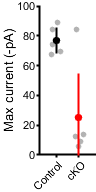

ylim([0 100])


figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Integral (-pC)';
dim1 = [1 2];
[fig3 h p3] = compare2(ConCharge,TectaTMCharge,conditions1,ylbl1,dim1)

not normal


fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 303
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p3 = 0.0043

p3

p3 = 0.0043

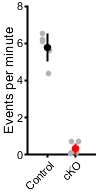

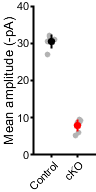

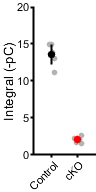

ylim([0 20])

subP = handleTheSubplot({fig1,fig2,fig3},[1 3]);

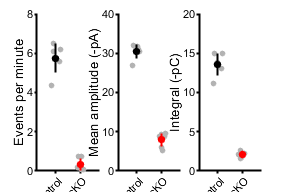

figQuality(subP,gca,[3 2])


[CorrP CorrA h] = fdr_BH([p1,p3],0.05)

CorrP =     0.0043    0.0043


CorrA =     0.0250    0.0500


h = 2×1 logical array
   1
   1


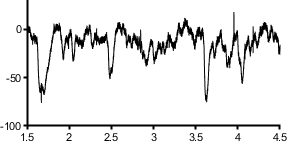

% plot examples

figure
flfl1 = medfilt1(Con2,20);
plot(timeCon2()/60,-flfl1(),'k','LineWidth', 1)
ylim([-100 30]);
xlim([1.5 4.5])
figQuality(gcf,gca,[3 1.5])

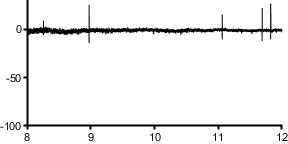


figure
tectaTM = medfilt1(TectaTM2,20);
plot(time2()/60,-tectaTM(),'k','LineWidth', 1)
ylim([-100 30]);
xlim([8 12])
figQuality(gcf,gca,[3 1.5])

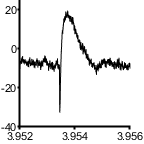


% example efferent 
figure
plot(timeCon2()/60,-Con2(),'k','LineWidth', 1)
ylim([-40 25]);
xlim([3.952 3.956])
figQuality(gcf,gca,[1.5 1.5])